# TAYLOR METHOD

clc
clear all
f = @(x,y) (y==2*x+1); %y'=2x+1  
fprime=@(x,y) (2); %y''=2

## Values 

 a = 0; %start
 b = 3; %end
 n = 6; %number of iterations           
 y0 = 1; %y0=1

 h = (b-a)/n; %step size = 0.5                                              
 x=[a zeros(1,n)]; 
 y=[y0 zeros(1,n)];


 for i = 1:n+1
     x(i+1)=x(i)+h;
     yprime=f(x(i),y(i))+(h/2)*fprime(x(i),y(i));
     y(i+1)=y(i)+h*yprime;
     fprintf('%5.4f  %11.8f\n', x(i), y(i));
 end

0.0000   1.00000000
0.5000   1.75000000
1.0000   2.00000000
1.5000   2.25000000
2.0000   2.50000000
2.5000   2.75000000
3.0000   3.00000000


## PLOT

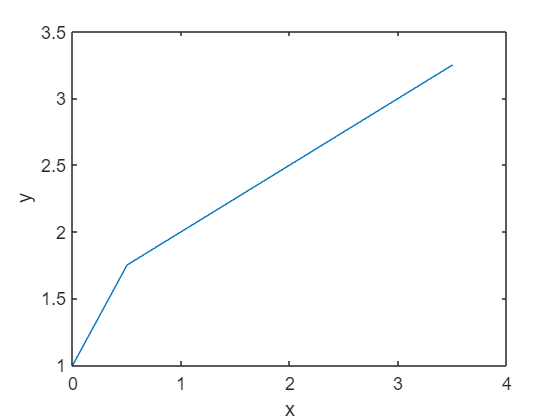

     figure (1)
     plot(x,y)
     xlabel ('x')
     ylabel('y')